## Analisis de la calidad de las imagenes y posible interpolación de datos 

### NDVI del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok



var_calidad = 89;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla


tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <=2022);
info_consulta = info_hdf(tmp,:);

[filas,~] = size(info_consulta);
disp("Num de imágenes: "+filas);

Num de imágenes: 519


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 2d para el promedio por día
arr_promedio_dia = zeros(1,filas);


Recuperar  la información

disp("Obteniendo información de "+filas+" imágenes");

Obteniendo información de 519 imágenes


bp=waitbar(0,'Obteniendo información'); 
for i=1:filas
    waitbar(i/filas,bp);
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %quitar las nubes y nieve y demas pixeles anomalos
    ndvi (disponibilidad ~= 0 & disponibilidad ~= 1)=NaN;
    
    %obtener la calidad y almacenarla en el campo correspondiente
    tmp_calidad = m_calidad_imagen(disponibilidad,calidad_total);
    info_consulta.Calidad(i) = tmp_calidad;

    if (tmp_calidad >= var_calidad)
        % promedio ndvi 
        arr_promedio_dia(i) = mean(ndvi,'all','omitnan');
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = ndvi;
    else
        % promedio ndvi 
        arr_promedio_dia(i) = nan;
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = nan;
    end

    % si se desea, mostrar cada imagen individual
    if debug_dibujar_mapa == true 
        m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,i+": NDVI ("+tmp_calidad+"%)",[0 1],ndvi_colormap,"NDVI");
        m_dibujar_kml(dir_data,"RH26",1,'b',"RH26");
        pause(debug_pausa);
    end
end
close(bp); 

### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

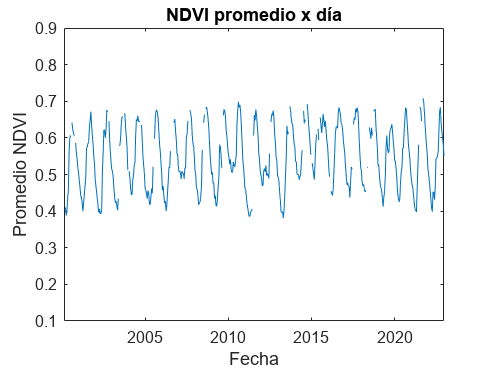

tmp_dias = table2array(info_consulta(:,["anio" "mes" "dia"] ));
t = datetime(tmp_dias(:,1) ,tmp_dias(:,2),tmp_dias(:,3));

figure;
plot(t,arr_promedio_dia);
%xlim([1 365]);
ylim([0.1 0.9]);
title('NDVI promedio x día');
xlabel('Fecha');
ylabel('Promedio NDVI');

exportgraphics(gca,"img/"+var_calidad+"_ndvi_promedio_diario.png",'Resolution',300) 

### 5.- Contar los nan consecutivos

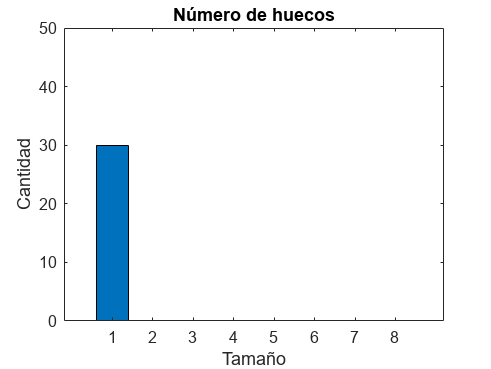

num_nan = zeros(1,length(arr_promedio_dia));
cnan=0;
for i=1:length(arr_promedio_dia)
    if(isnan(arr_promedio_dia(i)))
       cnan=cnan+1; 
    else
        if(cnan>0)
            num_nan(cnan)=num_nan(cnan)+1;
            cnan=0;
        end
    end
end

figure;
bar(num_nan(1:8));
ylim([0 50]);
title('Número de huecos');
xlabel('Tamaño');
ylabel('Cantidad');
exportgraphics(gca,"img/"+var_calidad+"_histo.png",'Resolution',300) 